## Perforated plate on porous material with hard backing

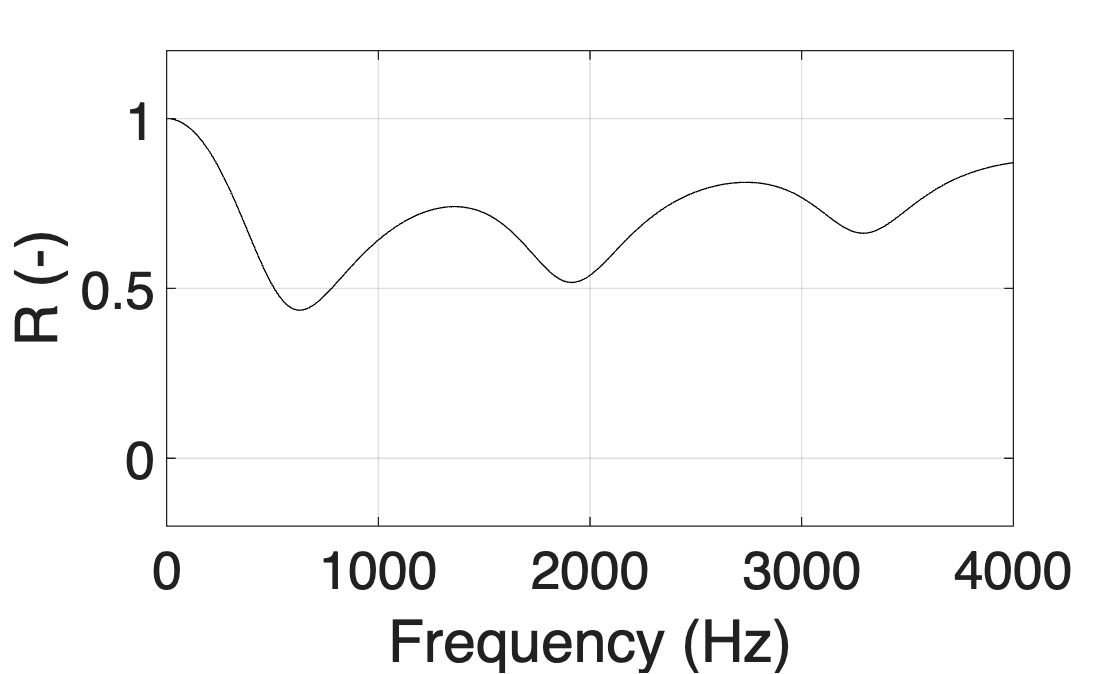

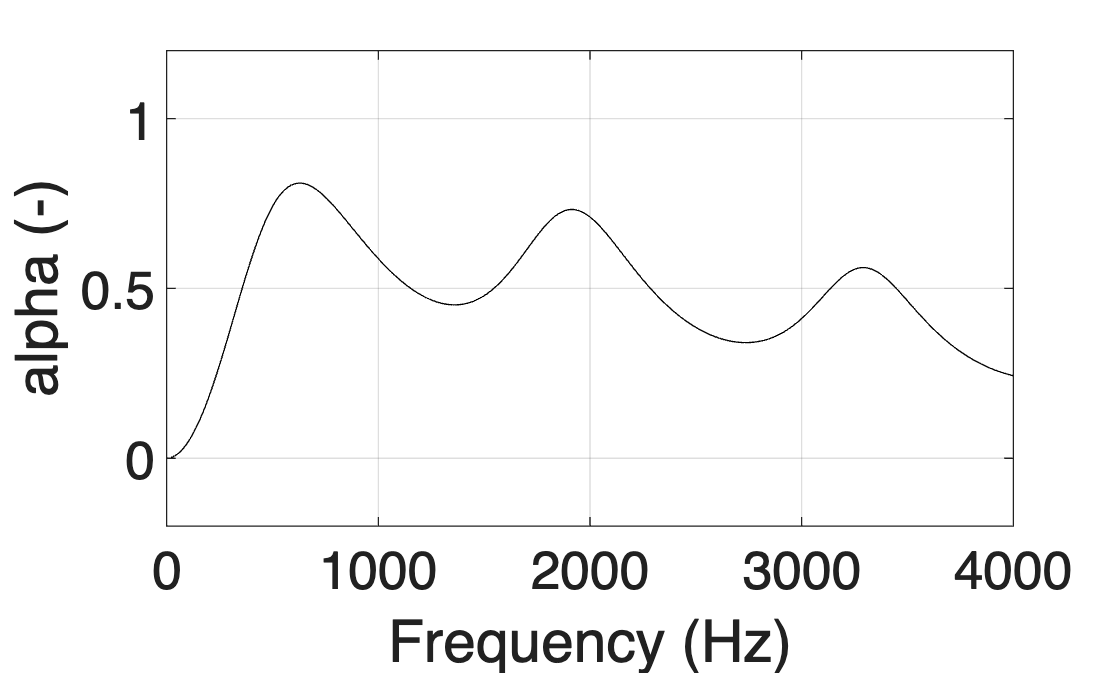

fmax = 4000;                                    % maximum frequency of interest
pt = 6;                  % perforated panel thickness (mm)
fres = 13000;            % flow resistivity porous material
poro = 0.35;              % porosity of porous material
d = 0.04;                 % thickness of porous material 
radius = 0.005;                                 % radius of perforation holes (m)
pr = 0.3;                                       % fraction of plate that is perforated

Rporouspanel(fres,poro,pt,fmax,d,radius,pr)

### Help functions

Feel free to modify to make it better!

function Rporouspanel(fres,poro,pt,fmax,d,radius,pr)
fv = 20:10:fmax;
omega = 2.*pi.*fv;
rho = 1.2;
c = 343;
k = omega./c;
Z = rho*c;
Zpo = Z./poro.*sqrt(1-j*(fres.*poro)./(rho*omega));
kpo = omega./(poro.*c).*sqrt(1-j*(fres.*poro)./(rho*omega));
mp = rho./pr.*(pt/1000+2.*radius);
Zp=Z+j.*omega.*mp-j.*Zpo.*cot(kpo.*d);
R = (Zp-Z)./(Zp+Z);

close all
figure(51)
plot(fv,abs(R),'k')
xlabel(['Frequency (Hz)'],'FontSize',20)
ylabel(['R (-)'],'FontSize',20)
set(gca,'FontSize',20)
grid on
axis([0 fmax -0.2 1.2])
box on
figure(52)
plot(fv,1-abs(R.^2),'k')
xlabel(['Frequency (Hz)'],'FontSize',20)
ylabel(['alpha (-)'],'FontSize',20)
set(gca,'FontSize',20)
grid on
axis([0 fmax -0.2 1.2])
box on

end